% REPOPULATE CHAIN WITH ENTRIES ONLY FROM ACTIVE EMITTERS.
function MC   = ParametricConversion(Chain)
         b    = find(Chain.b(end, :));    B = nnz(b);    MC.b = b;    MC.B = B;
                Q = Chain.Parameters ;
         M    = Q.M                  ;
     Prior    = Q.Prior              ;
% Annealed iteration.
           j = find(Chain.T == 1,1);
               I = Chain.Length    ;
  for i  = j : I
      l = i - j + 1          ;
         MC.D(l) = Chain.D(i);
         MC.F(l) = Chain.F(i);
         MC.G(l) = Chain.G(i);
         MC.H(l) = Chain.h(i);
% Monte Carlo Samples :
  if B == 1
     Xi = Chain.X(i,:);    X  =  reshape(Xi, [], M);    X  = X(:,b)    ;    MC.X(:,l)       = X         ;
     Yi = Chain.Y(i,:);    Y  =  reshape(Yi, [], M);    Y  = Y(:,b)    ;    MC.Y(:,l)       = Y         ;
     Zi = Chain.Z(i,:);    Z  =  reshape(Zi, [], M);    Z  = Z(:,b)    ;    MC.Z(:,l)       = Z         ;
  else
     Xi = Chain.X(i,:);    X  =  reshape(Xi, [], M);    X  = X(:,b)    ;    MC.X(:,1 : B,l) = X         ;
     Yi = Chain.Y(i,:);    Y  =  reshape(Yi, [], M);    Y  = Y(:,b)    ;    MC.Y(:,1 : B,l) = Y         ;
     Zi = Chain.Z(i,:);    Z  =  reshape(Zi, [], M);    Z  = Z(:,b)    ;    MC.Z(:,1 : B,l) = Z         ;
  end
     Di = Chain.D(i)  ;    Gi = Chain.G(i)         ;    Fi = Chain.F(i);    Hi              = Chain.h(i);
% Probabilities :
     MC.logPrior.b(l)    = logPriorLoad(b,Q)                                                              ;
     MC.logLikelihood(l) = logEmission(Fi,Hi,Gi, X,Y,Z, Q)                                                ;
     MC.logPrior.F(l)    = logPriorF(Fi,Prior)                                                            ;
     MC.logPrior.H(l)    = logPriorH(Hi,Prior)                                                            ;
     MC.logPrior.G(l)    = logPriorG(Gi,Prior)                                                            ;
     MC.logMotion(l)     = logMotion(X,Y,Z, Di, Q)                                                        ;
     MC.logPrior.D(l)    = logPriorD(Di,Prior)                                                            ;
     MC.logPosterior(l)  = MC.logPrior.b(l)                                                             ...
                         + MC.logLikelihood(l) + MC.logPrior.F(l) + MC.logPrior.H(l) + MC.logPrior.G(l) ...
                         + MC.logMotion(l) + MC.logPrior.D(l)                                             ;
  end
  MC.Length = I;    MC.Parameters = Q;
  MC.AnnealedLength = I - j          ;
end

Reset;      setModels ;    load reParametric.mat Parametric
    L = length(Models);

for l = 1 : L;    Model = Models(l);    Chain = importdata("Data/Inferred(" + Model + ").mat");    Parametric.(Model) = ParametricConversion(Chain);    end

save Data/ParametricF.mat Parametric

Models'

save reParametric.mat Parametric

Parametric.ATTM.logPrior

ans = struct with fields:
    b: [-100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 -100.5728 … ] (1×5250 double)
    F: [-12.1710 -12.1528 -12.1595 -12.1529 -12.1419 -12.1377 -12.1462 -12.1410 -12.1532 -12.1404 -12.1541 -12.1551 -12.1615 -12.1571 -12.1547 -12.1421 -12.1448 -12.1527 -12.1459 -12.1441 -12.1631 -12.1689 -12.1492 -12.1602 -12.1524 … ] (1×5250 double)
    H: [-11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 -11.2473 … ] (1×5250 double)
    G: [0.3908 0.3698 0.3794 0.3736 0.3577 0.3512 0.3645 0.3576 0.3691 0.3589 0.3728 0.3722 0.3821 0.3784 0.3735 0.3557 0.3650 0.3721 0.3653 0.3596 0.3843 0.3909 0.3687 0.3804 0.3698 0.3860 0.3720 0.3751 0.3639 0.3632 0.

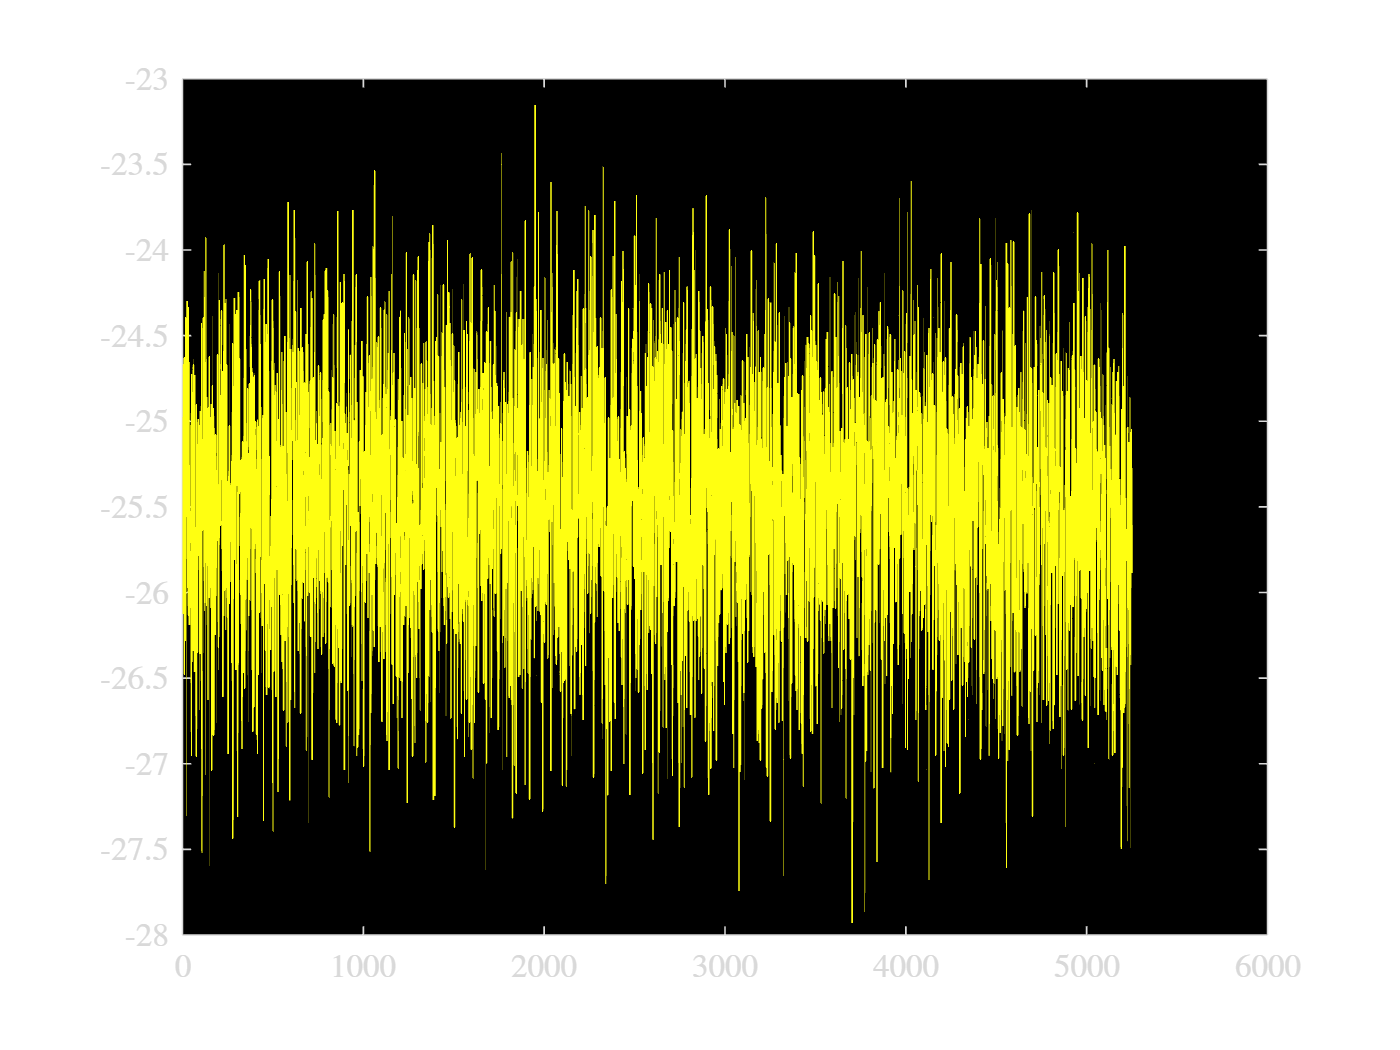

logPrior.Probability = Parametric.ATTM.logPrior.D + Parametric.ATTM.logPrior.F + Parametric.ATTM.logPrior.G + Parametric.ATTM.logPrior.H;

plot(logPrior.Probability)